# Lab Template

This is an mlx (matlab live script) template for the labs. Live Script allows you to mix code with text. Try to structure you code with one cell/section per exercise and keep all functions in the ./functions directory and all images in the ./images directory.

## Setting up environment

Here we clear old variables and make sure that ./functions and ./images are in the path.

% use clear to avoid unknowingly being dependent on 
% variables in the workspace defined by other scripts
% or in the command window
clear;

%add ./functions and ./images folders to path
addpath('./functions');
%addpath('./images');


trainImagesFile = 'train-images.idx3-ubyte';
testImagesFile = 't10k-images.idx3-ubyte';
testLabelsFile = 't10k-labels.idx1-ubyte';

XTrain = processMNISTimages(trainImagesFile);


Read MNIST image data...
Number of images in the dataset:  60000 ...


numTrainImages = size(XTrain,4);
XTest = processMNISTimages(testImagesFile);


Read MNIST image data...
Number of images in the dataset:  10000 ...


YTest = processMNISTlabels(testLabelsFile);


Read MNIST label data...
Number of labels in the dataset:  10000 ...


latentDim = 2;
imageSize = [28 28 1];

encoderLG = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);


encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);

executionEnvironment = "auto";


numEpochs = 3;
miniBatchSize = 512;
lr = 1e-3;
numIterations = floor(numTrainImages/miniBatchSize);
iteration = 0;

avgGradientsEncoder = [];
avgGradientsSquaredEncoder = [];
avgGradientsDecoder = [];
avgGradientsSquaredDecoder = [];


for epoch = 1:numEpochs
    tic;
    for i = 1:numIterations
        iteration = iteration + 1;
        idx = (i-1)*miniBatchSize+1:i*miniBatchSize;
        XBatch = XTrain(:,:,:,idx);
        XBatch = dlarray(single(XBatch), 'SSCB');
        
        if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
            XBatch = gpuArray(XBatch);           
        end 
            
        [infGrad, genGrad] = dlfeval(...
            @modelGradients, encoderNet, decoderNet, XBatch);
        
        [decoderNet.Learnables, avgGradientsDecoder, avgGradientsSquaredDecoder] = ...
            adamupdate(decoderNet.Learnables, ...
                genGrad, avgGradientsDecoder, avgGradientsSquaredDecoder, iteration, lr);
        [encoderNet.Learnables, avgGradientsEncoder, avgGradientsSquaredEncoder] = ...
            adamupdate(encoderNet.Learnables, ...
                infGrad, avgGradientsEncoder, avgGradientsSquaredEncoder, iteration, lr);
    end
    elapsedTime = toc;
    
    [z, zMean, zLogvar] = sampling(encoderNet, XTest);
    xPred = sigmoid(forward(decoderNet, z));
    elbo = ELBOloss(XTest, xPred, zMean, zLogvar);
    disp("Epoch : "+epoch+" Test ELBO loss = "+gather(extractdata(elbo))+...
        ". Time taken for epoch = "+ elapsedTime + "s")    
end

Epoch : 1 Test ELBO loss = 28.1003. Time taken for epoch = 185.3785s
Epoch : 2 Test ELBO loss = 26.9073. Time taken for epoch = 163.621s
Epoch : 3 Test ELBO loss = 25.9755. Time taken for epoch = 151.2378s


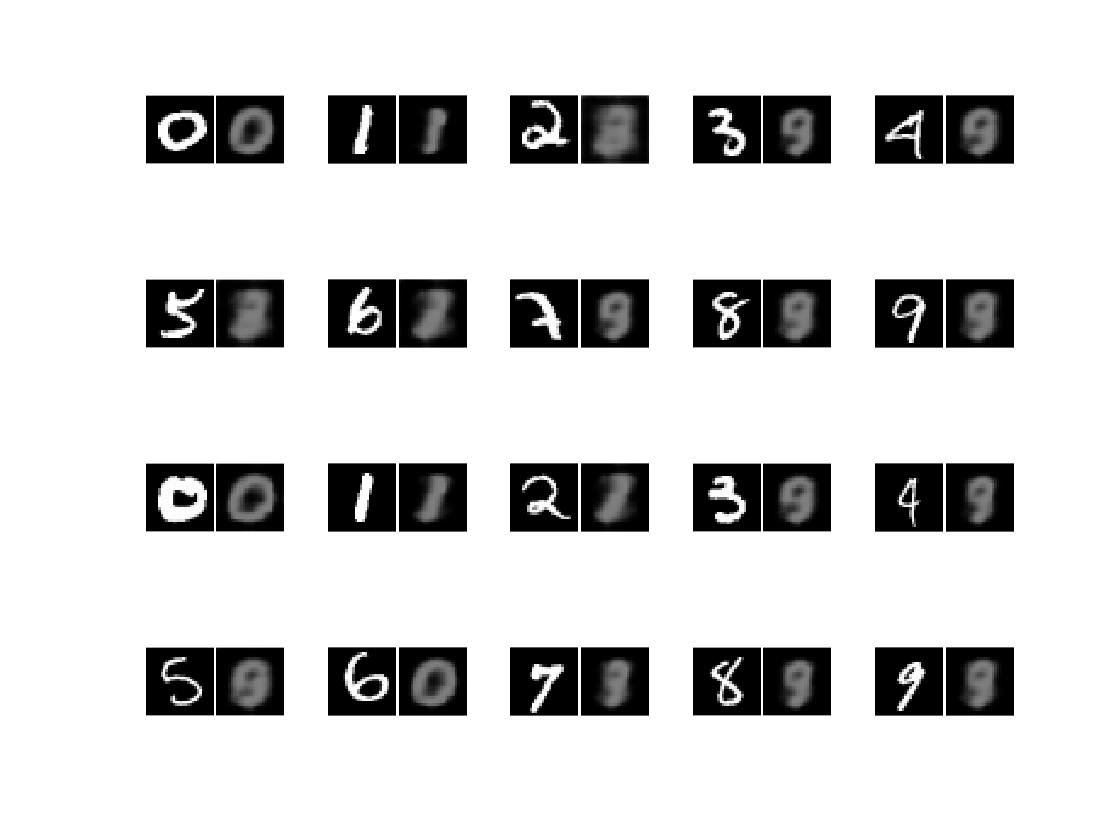

visualizeReconstruction(XTest, YTest, encoderNet, decoderNet)

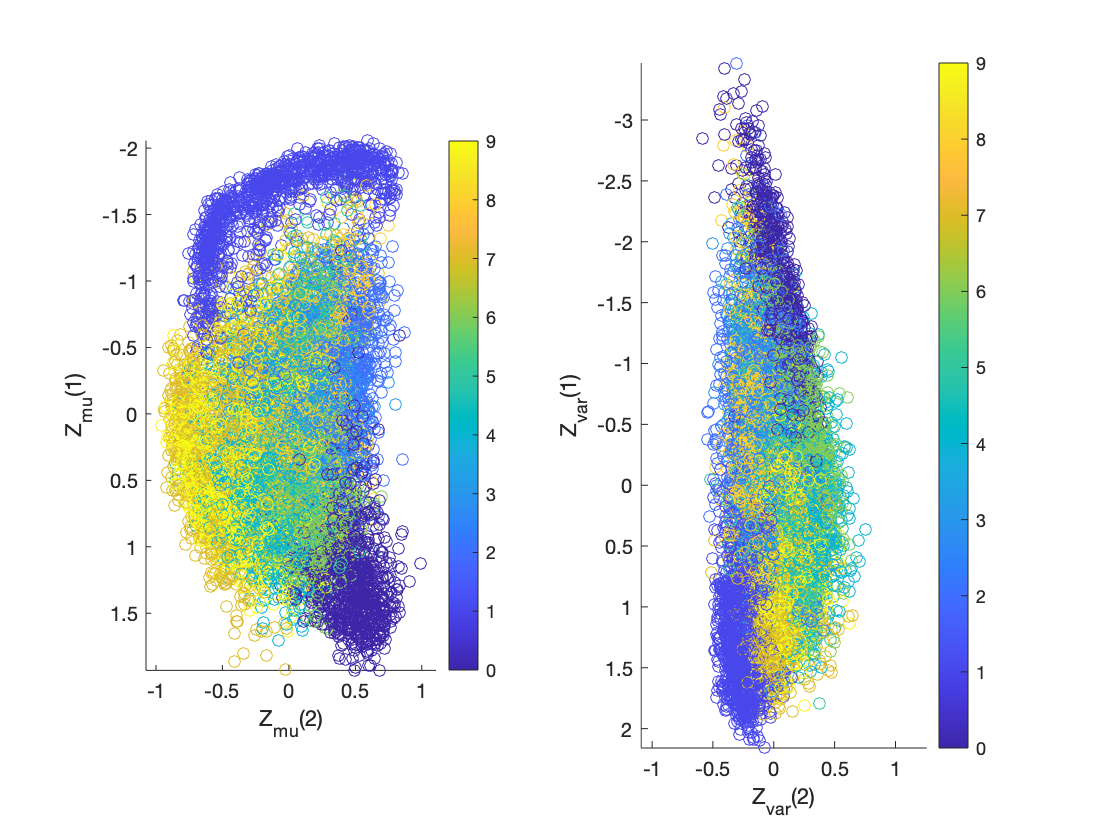

visualizeLatentSpace(XTest, YTest, encoderNet)

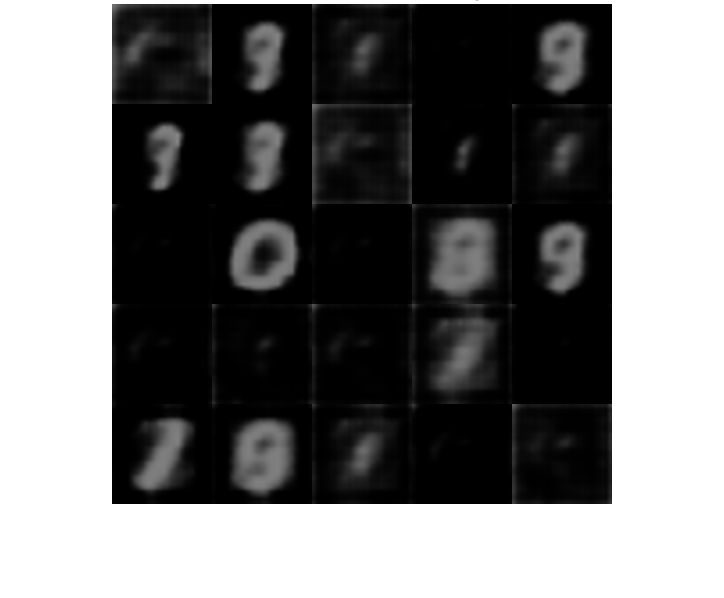

generate(decoderNet, latentDim)

% Functions

function [infGrad, genGrad] = modelGradients(encoderNet, decoderNet, x)
[z, zMean, zLogvar] = sampling(encoderNet, x);
xPred = sigmoid(forward(decoderNet, z));
loss = ELBOloss(x, xPred, zMean, zLogvar);
[genGrad, infGrad] = dlgradient(loss, decoderNet.Learnables, ...
    encoderNet.Learnables);
end

function [zSampled, zMean, zLogvar] = sampling(encoderNet, x)
compressed = forward(encoderNet, x);
d = size(compressed,1)/2;
zMean = compressed(1:d,:);
zLogvar = compressed(1+d:end,:);

sz = size(zMean);
epsilon = randn(sz);
sigma = exp(.5 * zLogvar);
z = epsilon .* sigma + zMean;
z = reshape(z, [1,1,sz]);
zSampled = dlarray(z, 'SSCB');
end

function elbo = ELBOloss(x, xPred, zMean, zLogvar)
squares = 0.5*(xPred-x).^2;
reconstructionLoss  = sum(squares, [1,2,3]);

KL = -.5 * sum(1 + zLogvar - zMean.^2 - exp(zLogvar), 1);

elbo = mean(reconstructionLoss + KL);
end

function visualizeReconstruction(XTest,YTest, encoderNet, decoderNet)
f = figure;
figure(f)
title("Example ground truth image vs. reconstructed image")
for i = 1:2
    for c=0:9
        idx = iRandomIdxOfClass(YTest,c);
        X = XTest(:,:,:,idx);

        [z, ~, ~] = sampling(encoderNet, X);
        XPred = sigmoid(forward(decoderNet, z));
        
        X = gather(extractdata(X));
        XPred = gather(extractdata(XPred));

        comparison = [X, ones(size(X,1),1), XPred];
        subplot(4,5,(i-1)*10+c+1), imshow(comparison,[]),
    end
end
end

function idx = iRandomIdxOfClass(T,c)
idx = T == categorical(c);
idx = find(idx);
idx = idx(randi(numel(idx),1));
end

function visualizeLatentSpace(XTest, YTest, encoderNet)
[~, zMean, zLogvar] = sampling(encoderNet, XTest);

zMean = stripdims(zMean)';
zMean = gather(extractdata(zMean));

zLogvar = stripdims(zLogvar)';
zLogvar = gather(extractdata(zLogvar));

[~,scoreMean] = pca(zMean);
[~,scoreLogvar] = pca(zLogvar);

c = parula(10);
f1 = figure;
figure(f1)
title("Latent space")

ah = subplot(1,2,1);
scatter(scoreMean(:,2),scoreMean(:,1),[],c(double(YTest),:));
ah.YDir = 'reverse';
axis equal
xlabel("Z_m_u(2)")
ylabel("Z_m_u(1)")
cb = colorbar; cb.Ticks = 0:(1/9):1; cb.TickLabels = string(0:9);

ah = subplot(1,2,2);
scatter(scoreLogvar(:,2),scoreLogvar(:,1),[],c(double(YTest),:));
ah.YDir = 'reverse';
xlabel("Z_v_a_r(2)")
ylabel("Z_v_a_r(1)")
cb = colorbar;  cb.Ticks = 0:(1/9):1; cb.TickLabels = string(0:9);
axis equal
end

function generate(decoderNet, latentDim)
randomNoise = dlarray(randn(1,1,latentDim,25),'SSCB');
generatedImage = sigmoid(predict(decoderNet, randomNoise));
generatedImage = extractdata(generatedImage);

f3 = figure;
figure(f3)
imshow(imtile(generatedImage, "ThumbnailSize", [100,100]))
title("Generated samples of digits")
drawnow
end

function X = processMNISTimages(filename)
[fileID,errmsg] = fopen(filename,'r','b');
if fileID < 0
    error(errmsg);
end

magicNum = fread(fileID,1,'int32',0,'b');
if magicNum == 2051
    fprintf('\nRead MNIST image data...\n')
end

numImages = fread(fileID,1,'int32',0,'b');
fprintf('Number of images in the dataset: %6d ...\n',numImages);
numRows = fread(fileID,1,'int32',0,'b');
numCols = fread(fileID,1,'int32',0,'b');

X = fread(fileID,inf,'unsigned char');

X = reshape(X,numCols,numRows,numImages);
X = permute(X,[2 1 3]);
X = X./255;
X = reshape(X, [28,28,1,size(X,3)]);
X = dlarray(X, 'SSCB');

fclose(fileID);
end

function Y = processMNISTlabels(filename)
[fileID,errmsg] = fopen(filename,'r','b');

if fileID < 0
    error(errmsg);
end

magicNum = fread(fileID,1,'int32',0,'b');
if magicNum == 2049
    fprintf('\nRead MNIST label data...\n')
end

numItems = fread(fileID,1,'int32',0,'b');
fprintf('Number of labels in the dataset: %6d ...\n',numItems);

Y = fread(fileID,inf,'unsigned char');

Y = categorical(Y);

fclose(fileID);
end
